# Example 7.7: Deterministic vs. Stochastic Decision-Making

Note: this script reproduces Example 7.7 (Section 7.6.1) of **Statistics for Chemical Engineers**: sizing the generator of Example 7.1 by minimizing different risk measures of the random cost. Victor Z UW-Madison, 2022 generator sizing example (stochastic)

clc; clear all; close all hidden;

## Load scenarios

generate scenarios for random load

rng(0)
N=1000;
X=wblrnd(10,2,N,1);

## Deterministic solution

find deterministic solution

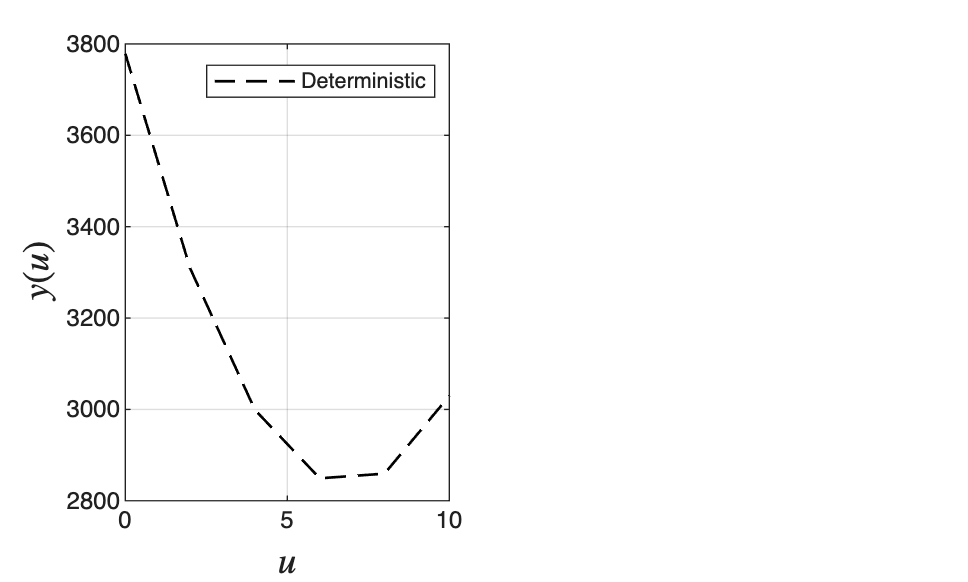

u=0:2:10;
x=max(X);

for k=1:length(u)
    yd(k)=myfun(u(k),x);
end

% visualize deterministic objective against decision
figure(2)
subplot(1,2,1)
plot(u,yd,'LineWidth',1,'Color','black','LineStyle','--')
grid on
hold on
xlabel('$u$','Interpreter','latex','FontSize',14)
ylabel('$y(u)$','Interpreter','latex','FontSize',14)
legend('Deterministic')

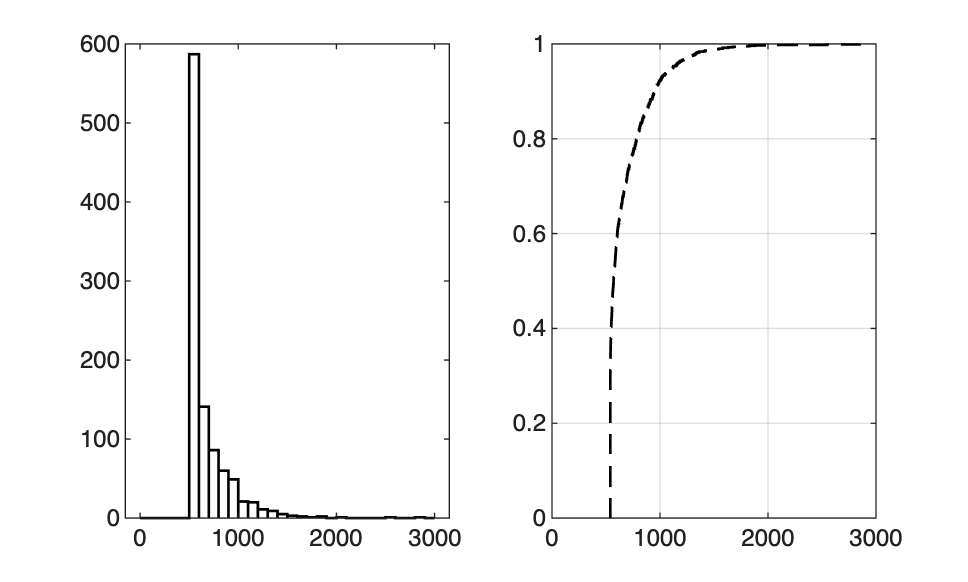


% find optimal size that 
idx=find(yd==min(yd));
ud=u(idx);

% evaluate how the deterministic solution ud behaves
% when it confronts uncertainty
figure(1)
yd=myfun(ud,X);
subplot(1,2,2)
[F,t]=ecdf(yd);
stairs(t,F,'LineWidth',1,'Color','black','LineStyle','--')
grid on
hold on

subplot(1,2,1)
histogram(yd,0:100:3000,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
hold on


% mean
Ed = mean(yd)

Ed = 674.1457

## Stochastic solution and risk measures

now find stochastic solution

for k=1:length(u)
    
y=myfun(u(k),X);

% mean
Ey(k)=mean(y);

% std dev
Vy(k)=sqrt(var(y));

% mean-sd
MVy(k)=Ey(k)+Vy(k);

% VaR (quantile)
Qy(k)=quantile(y,0.9);

% CVaR
loc = y >= Qy(k);
CVaRy(k) = mean(y(loc));

% worst-case
maxy(k)=max(y);

% probability of loss
loc = y > 2000;
Prob(k) = 100*sum(loc)/N;

end

## Optimizing a selected risk measure

select risk measure to optimize

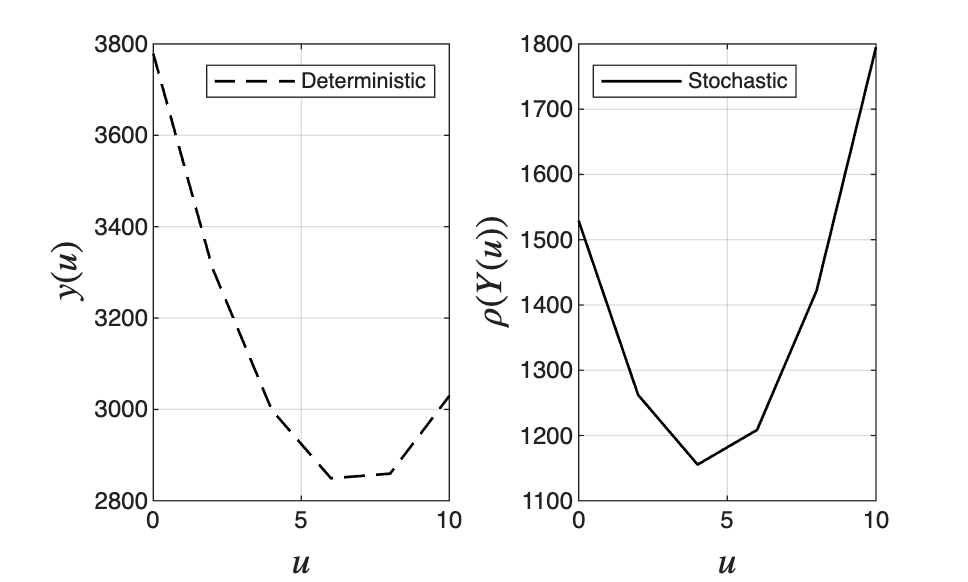

rm=CVaRy;

% visualize risk measure against decision
figure(2)
subplot(1,2,2)
plot(u,rm,'LineWidth',1,'Color','black','LineStyle','-')
grid on
hold on
xlabel('$u$','Interpreter','latex','FontSize',14)
ylabel('$\rho(Y(u))$','Interpreter','latex','FontSize',14)
legend('Stochastic','location','northwest')


% find solution that minimizes risk
 idx=find(rm==min(rm));
 us=u(idx);
 
% evaluate how stochastic solution behaves
% when it confronts uncertainty
ys=myfun(us,X);

% mean
Es = mean(ys)

Es = 460.5101

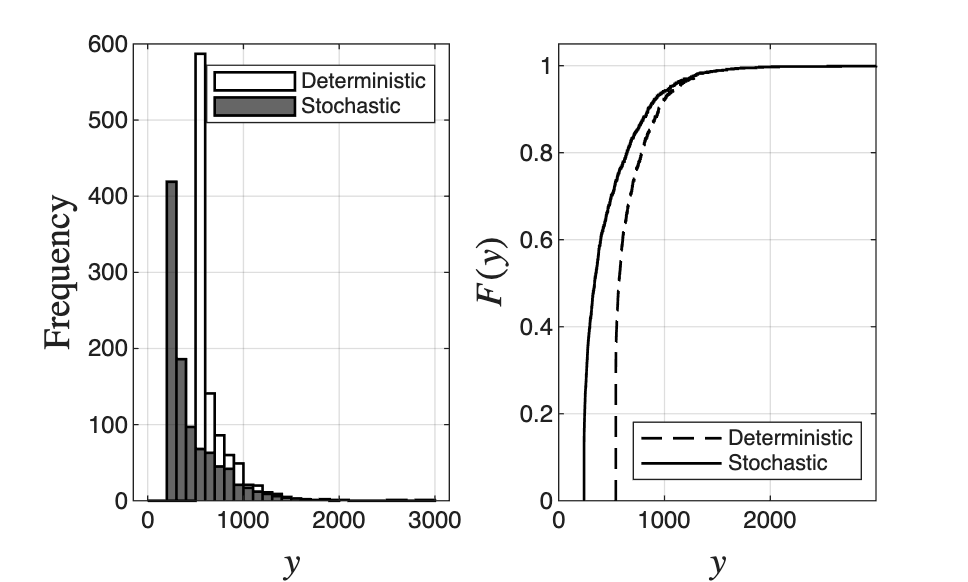


figure(1)
subplot(1,2,2)
[F,t]=ecdf(ys);
stairs(t,F,'LineWidth',1,'Color','black','LineStyle','-')
grid on
axis([ 0 max(ys) 0 1.05])
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$F(y)$','Interpreter','latex','FontSize',14)
legend('Deterministic','Stochastic','location','southeast')

subplot(1,2,1)
histogram(ys,0:100:3000,'Normalization','count','EdgeColor','black','FaceColor','black','LineWidth',1)
grid on
legend('Deterministic','Stochastic')
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)

print -depsc -r1200 ch7_generator_stoch.eps

## function definition

 function y=myfun(u,X)
 
   R = max(X-u,0);
 y = 5*(R.^2) + 15*u.^2;
 
 end

## Note

As in the book, stochastic optimization lets us shape the pdf/cdf of the cost; CVaR is particularly useful because the probability level alpha tunes the protection against high costs.